Training the Gaussian mixture model inside the Foreground Detector with the first 150 frames

%put the code in another script 
%run the output here, and can open up code in another script
foregroundDetector = vision.ForegroundDetector('NumGaussians', 3, ...
    'NumTrainingFrames', 50);

videoReader = VideoReader('visiontraffic.avi');
for i = 1:150
    frame = readFrame(videoReader); % read the next video frame
    foreground = step(foregroundDetector, frame);
end

 Segmentation Results

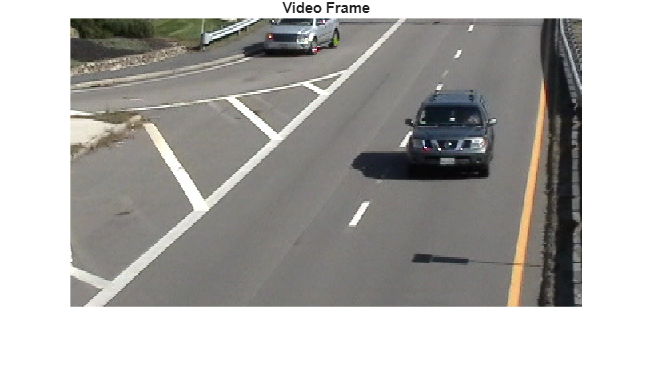

figure; imshow(frame); title('Video Frame');

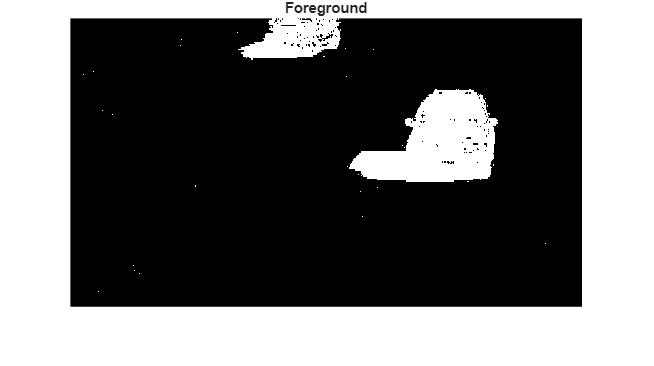

figure; imshow(foreground); title('Foreground');

Morphology to remove noise

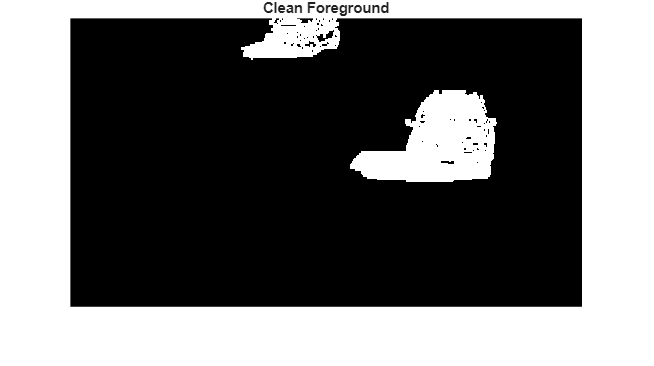

se = strel('square', 3);
filteredForeground = imopen(foreground, se);
figure; imshow(filteredForeground); title('Clean Foreground');

Find dimensions and bounding boxes of each object using Blob Analysis

blobAnalysis = vision.BlobAnalysis('BoundingBoxOutputPort', true, ...
    'AreaOutputPort', false, 'CentroidOutputPort', false, ...
    'MinimumBlobArea', 150);
bbox = step(blobAnalysis, filteredForeground);
result = insertShape(frame, 'Rectangle', bbox, 'ShapeColor', 'green');

Count number of cars and display results

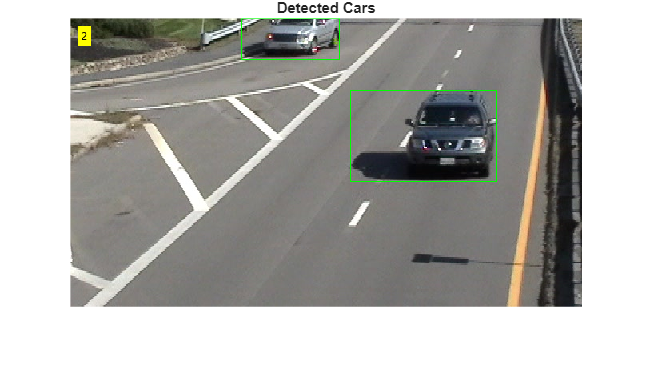

numCars = size(bbox, 1);
result = insertText(result, [10 10], numCars, 'BoxOpacity', 1, ...
    'FontSize', 14);
figure; imshow(result); title('Detected Cars');

videoPlayer = vision.VideoPlayer('Name', 'Detected Cars');
videoPlayer.Position(3:4) = [650,400];  % window size: [width, height]
se = strel('square', 3); % morphological filter for noise removal

while hasFrame(videoReader)

    frame = readFrame(videoReader); % read the next video frame

    % Detect the foreground in the current video frame
    foreground = step(foregroundDetector, frame);

    % Use morphological opening to remove noise in the foreground
    filteredForeground = imopen(foreground, se);

    % Detect the connected components with the specified minimum area, and
    % compute their bounding boxes
    bbox = step(blobAnalysis, filteredForeground);

    % Draw bounding boxes around the detected cars
    result = insertShape(frame, 'Rectangle', bbox, 'ShapeColor', 'green');

    % Display the number of cars found in the video frame
    numCars = size(bbox, 1);
    result = insertText(result, [10 10], numCars, 'BoxOpacity', 1, ...
        'FontSize', 14);

    step(videoPlayer, result);  % display the results
end